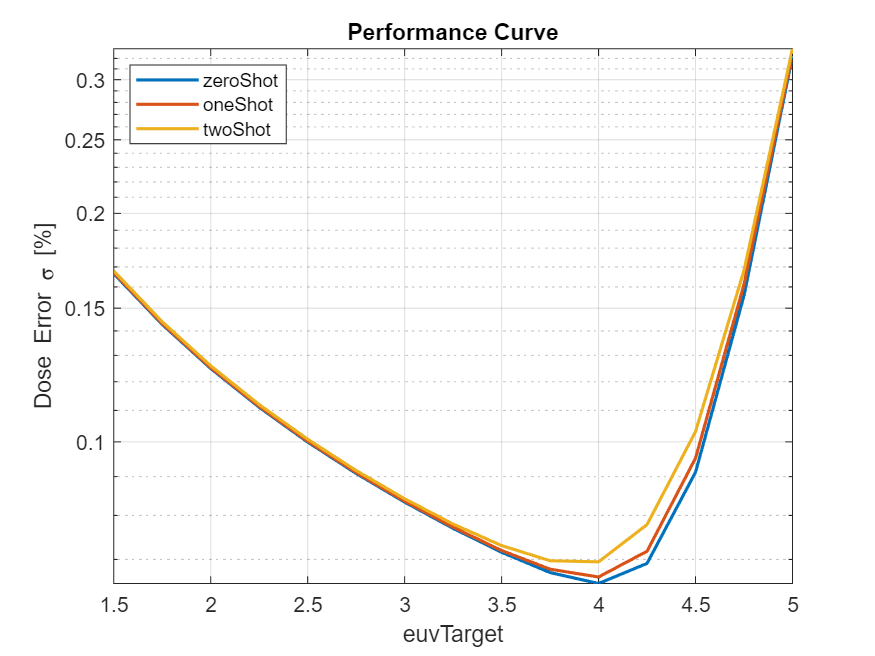

clear; clc; close all;
load('baseline_stats.mat');

zero_euvTarget = zeroShot(:,1);
zero_DEstd = zeroShot(:,2);
zero_OOSrate = zeroShot(:,3);

one_euvTarget = oneShot(:,1);
one_DEstd = oneShot(:,2);
one_OOSrate = oneShot(:,3);

two_euvTarget = twoShot(:,1);
two_DEstd = twoShot(:,2);
two_OOSrate = twoShot(:,3);

figure;
plot(zero_euvTarget,zero_DEstd,'LineWidth',1.5); grid on; hold on;
plot(one_euvTarget,one_DEstd,'LineWidth',1.5);
plot(two_euvTarget,two_DEstd,'LineWidth',1.5);
legend('zeroShot','oneShot','twoShot','Location','NorthWest');
xlabel('euvTarget'); ylabel('Dose Error \sigma [%]');
title('Performance Curve');
set(gca,'Yscale','log');